# Save in EEGLab format

p01_initialize;

fftEEG


Some menu items hidden. Use Preference menu to show them all.
eeglab: options file is ~/eeg_options.m
Retrieving plugin versions from server...
Retrieving download statistics...
EEGLAB: adding "ICLabel" v1.6 (see >> help eegplugin_iclabel)
EEGLAB: adding "clean_rawdata" v2.91 (see >> help eegplugin_clean_rawdata) - new version 2.10 available
EEGLAB: adding "dipfit" v5.4 (see >> help eegplugin_dipfit) - new version 5.5 available
EEGLAB: adding "firfilt" v2.8 (see >> help eegplugin_firfilt)


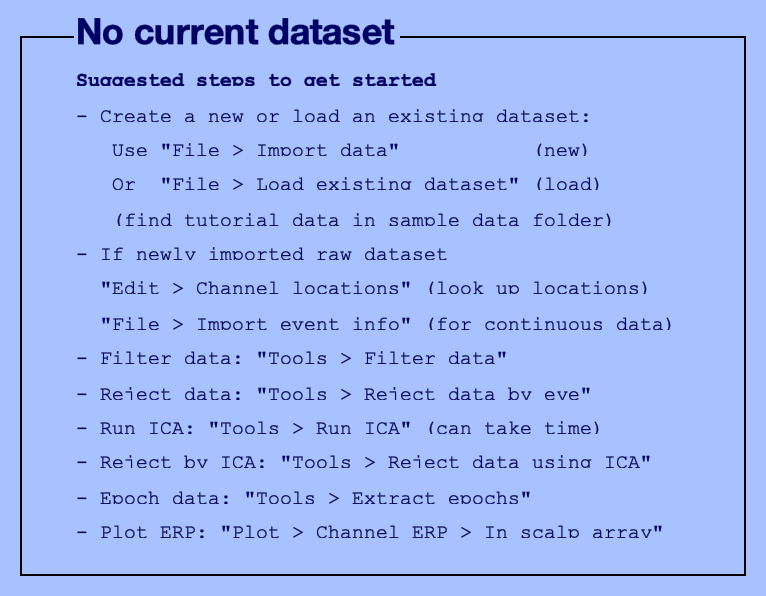

path_eeglab = '/Applications/eeglab2024.1';
addpath(path_eeglab);
eeglab;

Fs = 200;
signal_eeg = data_eeg.data_eeg_run;
signal_eeg = permute(signal_eeg,[2,1,3]);
util_eeglab = EEGLAButils;
EEG = util_eeglab.EEGLAB_setEEG_epoch(signal_eeg, sub, Fs);

pop_editset(): channel locations file '/Users/kana/Library/Mobile Documents/com~apple~CloudDocs/Codes/Antiphase-tap/antiphase_tapping_analysis_codes/toolbox_iwama/EEG_Atom/GSN129.sfp' found
readlocs(): 'sfp' format assumed from file extension
eeg_checkset warning: number of columns in data (129) does not match the number of channels (0): corrected
eeg_checkset warning: 3rd dimension size of data (12) does not match the number of epochs (0), corrected
eeg_checkset warning: number of columns in data (5200) does not match the number of points (129): corrected
eeg_checkset note: upper time limit (xmax) adjusted so (xmax-xmin)*srate+1 = number of frames



EEG = eeg_checkset(EEG);
filename = sprintf('block%s.set', block);
EEG = pop_saveset(EEG, 'filename', filename, 'filepath', cd);

Saving dataset...


EEG = eeg_checkset(EEG);

% Move the file to the first destination
movefile(sprintf("block%s*", block), sprintf("data/sub-%s/03_eeglab/", sub));